# Filter a Data Stream Using FFT

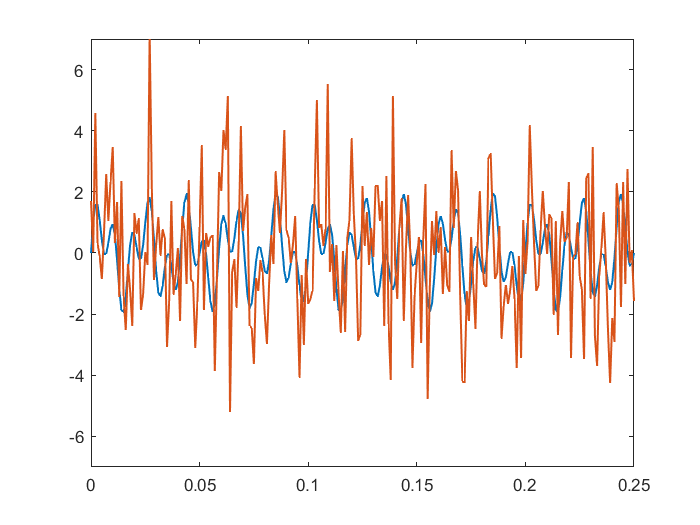

dx = 0.001;
x = 0:dx:1;

fx = sin(2*pi*50*x) + sin(2*pi*120*x);

figure(1);
plot(x,fx,'LineWidth',1.2);
axis([0 0.25 -7 7]);
noisy_fx = fx + 2*randn(size(x)); % Add normally distributed gaussian white noise
hold on;
plot(x,noisy_fx,'LineWidth',1.2);

## Filtering the data

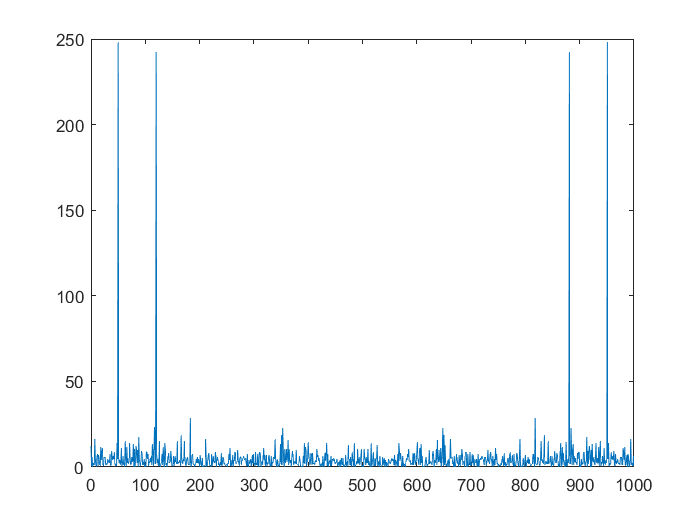

N = length(x);
fw = fft(noisy_fx,N);

PSD = fw.*conj(fw)/N; % Power spectrum density (how much power is in each spectrum), this is just the inner product of fw iwth itself

figure(2);
plot((1:N)-1,PSD);

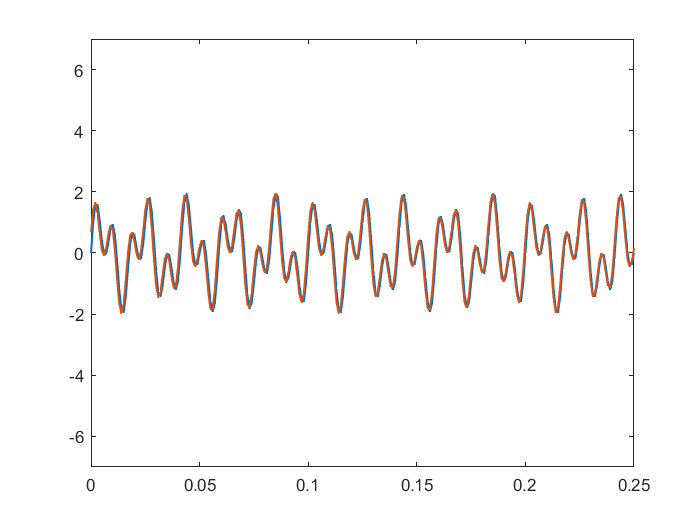

filter_array = PSD > 50;
fw_filtered = fw.*filter_array;
filtered_fx = ifft(fw_filtered,N);

figure(3);
plot(x,fx,'LineWidth',1.2);
axis([0 0.25 -7 7]);
hold on;
plot(x,filtered_fx,'LineWidth',1.2);